clear all;
close all;

%A = [-1,0;0,-2];
A = [0,1;-3,2];
A3 = [0,1;-1,0];
A4 = [0,0;0,-1];
A5 = [0,2;0,1];
A6 = [0.5,0;0,-0.5];
A7 = [0,0.1;0.2,1];
A8 = [0,0;0,1];
    T = 6;
    [w J]=eig(A)

w =    0.2887 - 0.4082i   0.2887 + 0.4082i
   0.8660 + 0.0000i   0.8660 + 0.0000i


J =    1.0000 + 1.4142i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 - 1.4142i


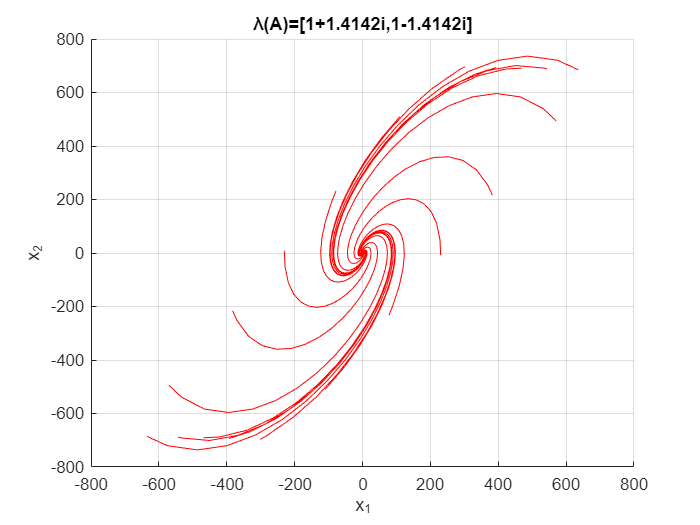

    figure()
    hold on
    grid on

    a = 0:(pi/10):(2*pi);
    X1 =[cos(a);sin(a)];
        X2 = X1./[max(abs(X1))];
    max(abs(X1));
    M = size(X2,2);

    for m=1:M
        x0 = X2(:,m);
        out = sim('untitled',T);
        plot(x(:,1),x(:,2),'r-');
        title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']']);
        xlabel('x_1'); 
        ylabel('x_2');
    % xlim([-1 -1])
    % ylim([1 1])
    end